rule = [0  0  0  1  1  1  1  0]

rule =      0     0     0     1     1     1     1     0


function out_bit = apply_rule(in_vec3, rule)
    % three bits correspond the colors, will produce an output bit based on
    % the rule
    % ⬜ -> 0, ⬛ -> 1

    % ⬛⬛⬛
    if in_vec3(1) && in_vec3(2) && in_vec3(3)
        out_bit = rule(1);
    
    % ⬛⬛⬜
    elseif in_vec3(1) && in_vec3(2) && ~in_vec3(3)
        out_bit = rule(2);

    % ⬛⬜⬛
    elseif in_vec3(1) && ~in_vec3(2) && in_vec3(3)
        out_bit = rule(3);

    % ⬛⬜⬜
    elseif in_vec3(1) && ~in_vec3(2) && ~in_vec3(3)
        out_bit = rule(4);

    % ⬜⬛⬛
    elseif ~in_vec3(1) && in_vec3(2) && in_vec3(3)
        out_bit = rule(5);

    % ⬜⬛⬜
    elseif ~in_vec3(1) && in_vec3(2) && ~in_vec3(3)
        out_bit = rule(6);
    
    % ⬜⬜⬛
    elseif ~in_vec3(1) && ~in_vec3(2) && in_vec3(3)
        out_bit = rule(7);

    % ⬜⬜⬜
    else
        out_bit = rule(8);
    end
end
function s_1 = next_eca_state(s_0, rule)
    n = length(s_0);
    s_1 = zeros(1, n) + -1;
    s_1(1) = apply_rule([s_0(end) s_0(1:2)], rule); % wrap around start
    for i=1:n-2
        vec3 = s_0(i:i+2);
        s_1(i+1) = apply_rule(vec3, rule);
    end
    s_1(end) = apply_rule([s_0(end-1:end) s_0(1)], rule); % wrap around end
end

iterations = 8;
width = 17;
eca = zeros(iterations, width);
% set middle to 1
eca(1, ceil(width/2)) = 1; 
for i=1:iterations
    eca(i+1, :) = next_eca_state(eca(i, :), rule);
end
eca

eca =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     1     1     0     1     1     1     1     0     0     0     0     0
     0     0     0     0     1     1     0     0     1     0     0     0     1     0     0     0     0
     0     0     0     1     1     0     1     1     1     1     0     1     1     1     0     0     0
     0     0     1     1     0     0     1     0     0     0     0     1     0     0     1     0     0
     0     1     1     0     1     1     1     1     0     0     1     1     1     1     1     1     0
     1     1     0     0     1     0     0     0     1     1     1     0     0     0     0     0     1


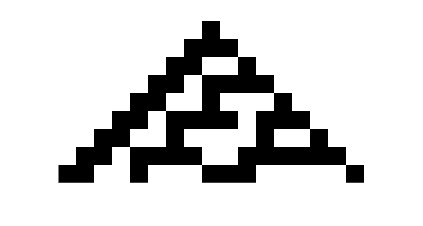

imshow(not(eca), "InitialMagnification", 2000)

apply_rule([1 0 0], rule)

ans =      1


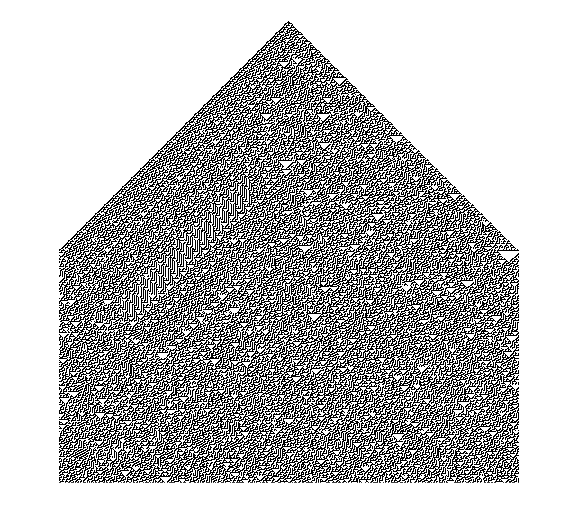

function saved = run_eca(start_state, rule, iterations)
    width = length(start_state);
    eca = zeros(iterations, width);
    eca(1, :) = start_state;
    for i=1:iterations
        eca(i+1, :) = next_eca_state(eca(i, :), rule);
    end
    saved = eca;
end
width = 512;
start = zeros(1, width);
start(floor(width/2)) = 1; 
iterations = 512;
eca = run_eca(start, rule, iterations);
imshow(not(eca), "InitialMagnification",2000)

function [final_state, col] = run_eca_col(start_state, rule, iterations)
    col = zeros(1, iterations);
    middle = floor(length(start_state) / 2);
    for i=1:iterations
        col(i) = start_state(middle);
        start_state = next_eca_state(start_state, rule);
    end

    col(end) = start_state(middle);
    final_state = start_state;
end
[f, col] = run_eca_col(start, rule, iterations)

f =      0     1     1     0     0     0     0     1     0     0     1     1     1     0     1     1     1     0     1     0     1     1     1     0     1     0     0     1     1     1     1     0     1     0     1     0     1     0     1     0     1     1     1     0     1     1     0     0     0     1


col =      1     1     0     1     1     1     0     0     1     1     0     0     0     1     0     1     1     0     0     1     0     0     1     1     1     0     1     0     1     1     1     0     0     1     1     1     0     1     0     1     0     1     1     0     0     0     0     1     1     0


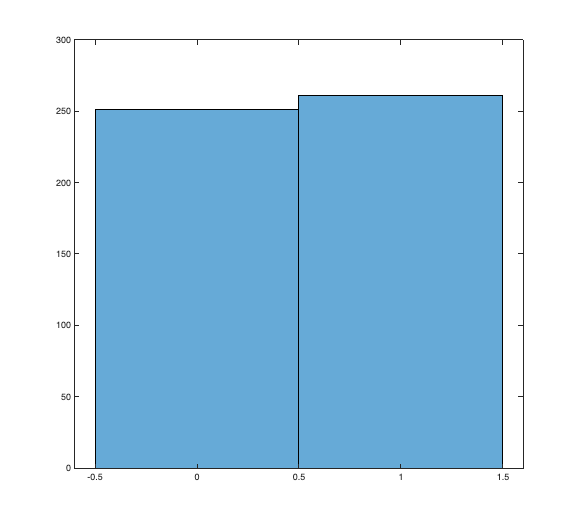

histogram(col)